# **RS-WISP-01: Geo-Stationary Orbit Generation**

**WorkerInSpace Senior Researcher**

**Hongseok Kim**

**1/14/2025**

## **I. Scope**

  Review of the two-Body Model and generate LEO parking orbit, Geo-Transfer Orbit and GEO Stational Orbit

Starting from two-body model


$$\ddot{\mathit{\mathbf{r}}} =-\mu \frac{\vec{\mathit{\mathbf{r}}} }{{\left|\vec{\mathit{\mathbf{r}}} \right|}^3 }$$


### I.0 Internal function for orbit Propagator for Given Dynamics

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

### **I.1 Satellite Initial Orbit Parameter and Simulation Parameter Setting**

clear; clc;
addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_01_GEO_Orbit_Generation')
load("earth_coastline.mat")

Tsim = 86400;
delt = 1;
N = floor(Tsim/delt);
tVec = [0:N-1]' * delt;


%% Define Initial Time
initial_epoch = posixtime(datetime('2024-03-21 00:00:00'));


elapsed_days = 0;
%% Define Current time
current_epoch = initial_epoch + elapsed_days * 24 * 3600;
epoch_datetime = datetime(current_epoch + tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');
epoch = [epoch_datetime.Year, epoch_datetime.Month, epoch_datetime.Day, epoch_datetime.Hour, epoch_datetime.Minute, epoch_datetime.Second];
disp(epoch_datetime(1))

   03/21/2024 00:00:00




% Orbit Contstant
J2 = 0.00108248;
R_Earth = 6378.1363;
mu = 398600.4415;

%% Define Initial Orbit Parameter
SMA = 24434.864; 
ecc = 0.728693;
inc = 6;
RAAN = 401.783;
AOP = 178.060;
theta = 59.988;
orbit_period = 2*pi* sqrt(SMA^3/mu)

orbit_period = 3.8012e+04




% Define Orbit Propagator
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,tVec);
r = y(:,1:3);
v = y(:,4:6);

r(end,:)

ans = 1.0e+04 *

    3.4496    1.3535   -0.1355


v(end,:)

ans =     0.6136    2.1893    0.1286


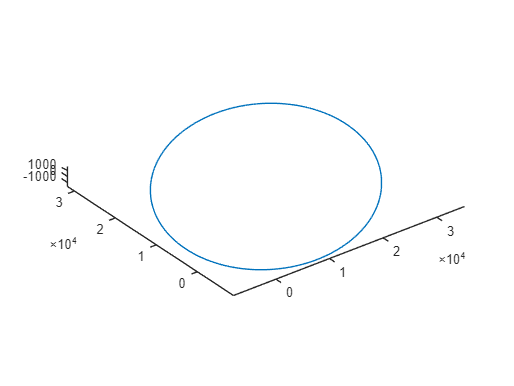


plot3(r(:,1),r(:,2),r(:,3))
axis('equal')



r(end,:),v(end,:)

ans = 1.0e+04 *

    3.4496    1.3535   -0.1355


ans =     0.6136    2.1893    0.1286



[SMA,ecc,inc,RAAN,AOP,theta] = ijk2kepler_hs(r(end,:),v(end,:))

SMA = 2.4435e+04

ecc = 0.7287

inc = 6.0000

RAAN = 41.7830

AOP = 178.0600

theta = 161.4772